# **Vision Artificial. GIEC - Sistemas de Vision Artificial. GIC**

# **Tema 3. Transformada Watershed**

**  Departamento de Electrónica. Universidad de Alcalá.**

## **Segmentación basada en regiones, watershed**

La Transformada Watershed aplica conceptos topológicos para segmentar una imagen, viendo esta, en niveles de gris, como una superficie con embalses (catchment basins), mínimos de la imagen, que se van llenando de agua. La transformada devuelve las presas o diques (watershed lines) que habría que poner para que el agua no pasase de un embalse a otro.

Entender la Transformada Watershed requiere que se piense en una imagen como una superficie. Por ejemplo, considere la imagen de abajo:

 	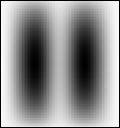         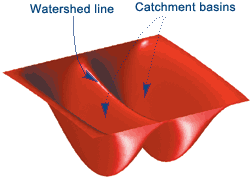

Figura 1. Imagen generada sintéticamente de dos manchas oscuras y su interpretación por parte del algoritmo watershed.    

Si imaginas que las áreas brillantes son "altas" y las oscuras "bajas", entonces podría parecerse a la superficie de la derecha. Con las superficies, es natural pensar en términos de embalses (catchment basins) y de diques (watershed lines). La clave para utilizar la función watershed para la segmentación es ésta: Cambie su imagen en otra imagen cuyas embalses (zonas oscuras) sean los objetos que desea identificar.

Este algoritmo está implementado en Matlab mediante la función `watershed`, que se aplicaría a una imagen cuyos objetos a segmentar serían los valores mínimos de la imagen.

### **Ejemplo 1. Transformada de Watershed**

close all;
clear all;
clc;

Se crea una imagen binaria que contenga dos objetos circulares superpuestos y se muestran

center1 = -10;
center2 = -center1;
dist = sqrt(2*(2*center1)^2);
radius = dist/2 * 1.4;
lims = [floor(center1-1.2*radius) ceil(center2+1.2*radius)];
[x,y] = meshgrid(lims(1):lims(2));
bw1 = sqrt((x-center1).^2 + (y-center1).^2) <= radius;
bw2 = sqrt((x-center2).^2 + (y-center2).^2) <= radius;
bw = bw1 | bw2;
figure
imshow(bw,'InitialMagnification','fit'), 
title('Dos objetos circulares superpuestos')

Se calcula la transformación de distancia de la imagen binaria complementada.

nbw = ~bw;
D = bwdist(nbw);
figure
imshow(D,[],'InitialMagnification','fit')
title('Transformación de distancia de la imagen binaria complementada')

Se complementa la transformación de distancia y se fuerzan los píxeles que no pertenezcan a los objetos a valor `Inf`

D = -D;
D(nbw) = -Inf;   
imshow(D,[],'InitialMagnification','fit')
title('Transformación de distancia complementada');

Se calcula la transformación de Watershed y se visualiza la matriz de etiquetas resultante como una imagen RGB

L = watershed(D);
rgb = label2rgb(L,'jet',[.5 .5 .5]);
figure
imshow(rgb,'InitialMagnification','fit')
title(sprintf('Transformada Watershed. Objetos segmentados: %d',max(max(L,[],1),[],2)));

**¿Qué ocurriría si en lugar de utilizar la imagen binaria complementada (**`~bw`**) se utilizase (**`bw`**)? realice el cambio y comente los resultados.**

### **Ejemplo 2. Transformada de Watershed**

También se puede trabajar con la función *dist* para hacer que las regiones oscuras de la imagen se correspondan con los objetos a segmentar, y luego aplicar la Transformada Watershed, como se observa en el siguiente ejemplo (en cuya etapa final se hace un procesado de los resultados de la transformada para evitar el problema de la sobre-segmentación):

close all,clear all;
I=imread('rice.tif');
figure, imshow(I,'InitialMagnification','fit'), title('Imagen original');

level = graythresh(I);
bw = im2bw(I,level);
figure, imshow(~bw,'InitialMagnification','fit'), title('Imagen sobre la que se calcula la dist')

%Calcula la funcion distancia
D = bwdist(~bw);
figure, imshow(D,[],'InitialMagnification','fit')
title('Funcion distancia a ~bw')

%Se complementa la dist, y se fuerza que los objetos que no pertenezcan a los objetos 
%sean  -Inf.
D = -D;
D(~bw) = -Inf;
 
 %Segmentacion directa a partir de la transformada de Watershed.
L = watershed(D);
rgb = label2rgb(L,'jet',[.5 .5 .5]);
figure, imshow(rgb,'InitialMagnification','fit')
title('Transformada Watershed de la funcion distancia ¿sobresegmentación?')
disp('Observe sobre-segmentacion');

**Observe el resultado ¿Existe sobre-segmentación, es decir, se han segmentado muchos más objetos de los que hay en la imagen?**